# Examples 7.2 and 7.3: Decision-Maker Disagreement and Attitudes Towards Risk

Note: this script reproduces Examples 7.2 and 7.3 (Section 7.2) of **Statistics for Chemical Engineers**: two options with random costs, one with a lower mean and one with a lower variance. Victor Z UW-Madison, 2023 compare alternatives using mean-variance

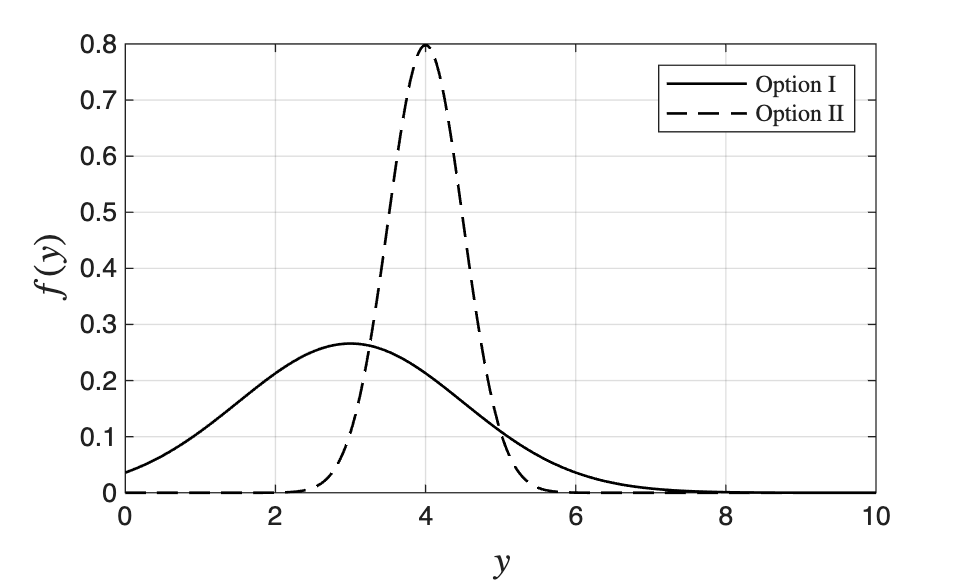

clc; clear all; close all hidden; format long e;

x=linspace(0,10,1000);

figure(1)
plot(x,normpdf(x,3,1.5),'LineWidth',1,'Color','black','LineStyle','-')
hold on
plot(x,normpdf(x,4,0.5),'LineWidth',1,'Color','black','LineStyle','--')
grid on
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$f(y)$','Interpreter','latex','FontSize',14)
legend('Option I','Option II','Interpreter','latex','location','northeast')
print -depsc ch7_mean_var_options.eps

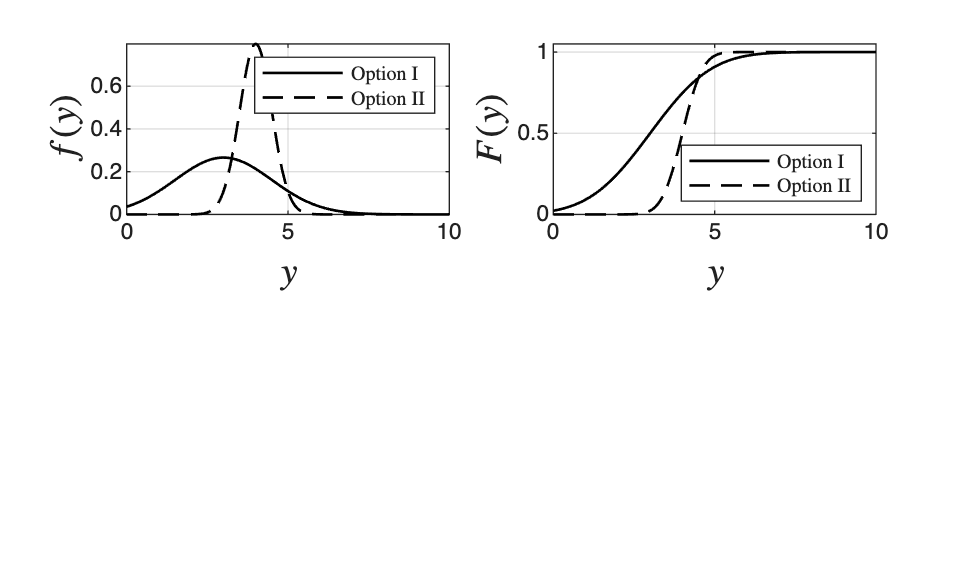


figure(2)
subplot(2,2,1)
plot(x,normpdf(x,3,1.5),'LineWidth',1,'Color','black','LineStyle','-')
hold on
plot(x,normpdf(x,4,0.5),'LineWidth',1,'Color','black','LineStyle','--')
grid on
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$f(y)$','Interpreter','latex','FontSize',14)
legend('Option I','Option II','Interpreter','latex','location','northeast')
subplot(2,2,2)
plot(x,normcdf(x,3,1.5),'LineWidth',1,'Color','black','LineStyle','-')
hold on
plot(x,normcdf(x,4,0.5),'LineWidth',1,'Color','black','LineStyle','--')
grid on
legend('Option I','Option II','Interpreter','latex','location','southeast')
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$F(y)$','Interpreter','latex','FontSize',14)
axis([0 10 0 1.05])
print -depsc ch7_mean_var_options_pdf_cdf.eps

## Mean and variance (Example 7.2)

summarizing statistics

y=5;
ploss1=1-normcdf(y,3,1.5)

ploss1 =      9.121121972586788e-02

ploss2=1-normcdf(y,4,0.5)

ploss2 =      2.275013194817921e-02


y=4;
ploss1=1-normcdf(y,3,1.5)

ploss1 =      2.524925375469229e-01

ploss2=1-normcdf(y,4,0.5)

ploss2 =      5.000000000000000e-01


alpha=0.9;
Q1=norminv(alpha,3,1.5)

Q1 =      4.922327348316901e+00

Q2=norminv(alpha,4,0.5)

Q2 =      4.640775782772300e+00


N=1000;
rng(1)
X1=normrnd(3,1.5,N,1);
X2=normrnd(4,0.5,N,1);

## Expected shortfall and attitudes towards risk (Example 7.3)

expected shortfall (CVaR)

loc = X1 >= Q1;
CVaR1 = mean(X1(loc))

CVaR1 =      5.658086351700798e+00


loc = X2 >= Q2;
CVaR2 = mean(X2(loc))

CVaR2 =      4.895405953875769e+00


% alternative way to compute expected loss
S1=0;
S2=0;
for k=1:N
    S1=S1+(Q1+(1/(1-alpha))*max(X1(k)-Q1,0));
    S2=S2+(Q2+(1/(1-alpha))*max(X2(k)-Q2,0));
end
CVaR1=S1/N

CVaR1 =      5.628655991565322e+00

CVaR2=S2/N

CVaR2 =      4.979433910339893e+00

## Note

As in the book, the mean and the variance lead to contradictory decisions; risk measures that look at the tails of the pdf capture the attitude of the decision-maker toward risk.